# ME: 6240 Long Homework #2

Due 3/29/2021

#### Dynamic State Estimation

### Michael Swafford

clear all

The for this long homework is to walk through an implementation for a recursive Bayesian filter and a linear Kalman filter with provided simulated data.

#### First, we are going to implement a simple recursive Bayesian filter. Consider a robot that resides in a one-dimensional world consisting of 16 discrete spots that are numbered by integers from 0 to 15 by whole numbers. Assume that the spots are arranged in a circle such that spots 0 and 15 are next to each other. 

#### The robot cannot sense its current location directly, however, spots 0, 6, 7, 10, and 11 contain an observable landmark whereas all other places do not. All five of these landmarks are exactly the same. The likelihood that the robot observes the landmark given it is in one of the landmark spots is 0.75. For all other spots, the likelihood of observing the landmark is 0.3.

#### For each spot on the circle we wish to compute the probability that the robot is in that place given that the following sequence of actions is carried out deterministically (process noise is 0) and the following sequence of observations are:

- The robot detects a landmark

- The robot moves 4 spots in the positive direction and detects a landmark

- The robot moves 5 spots in the negative directions and detects a landmark

- The robot moves another 7 spots in the negative direction and does not detect a landmark

- the robot remains in place. 

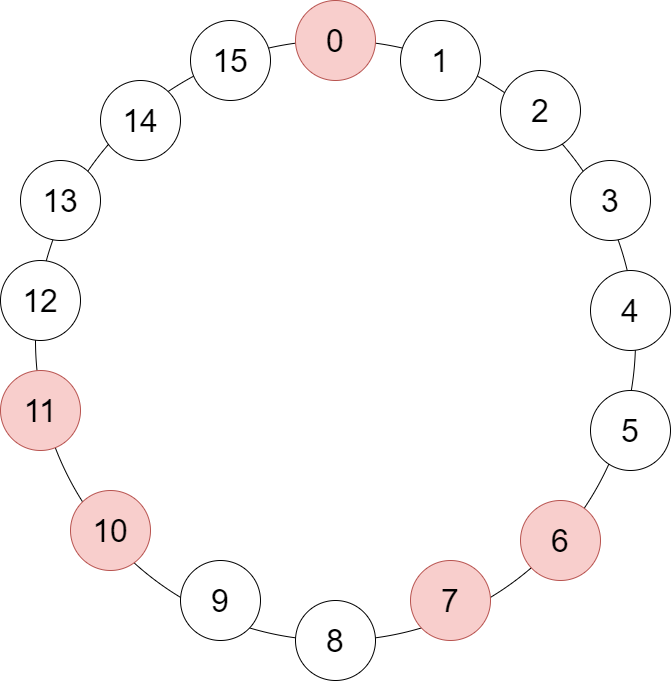

Diagram of robot world and highlight of landmark locations in red

# 1) Based on the information given in the prompt, describe in words the probability of the robot detecting a landmark at each of the spots and provide a plot of the likelihoods as a bar graph with the heights of the bars as the probabilities. Integrate the likelihood distribution over its base of support (sum of the likelihoods). Is this likelihood distribution a proper probability density function? Why or why not?

### The probability that the robot detects a landmark at each of the spots is the likelihood of detection given the spot is a landmark (or not). $\sum_{i=0}^{15} P(Detection|Landmark)+\sum_{i=0}^{15}P(Detection|!Landmark)$

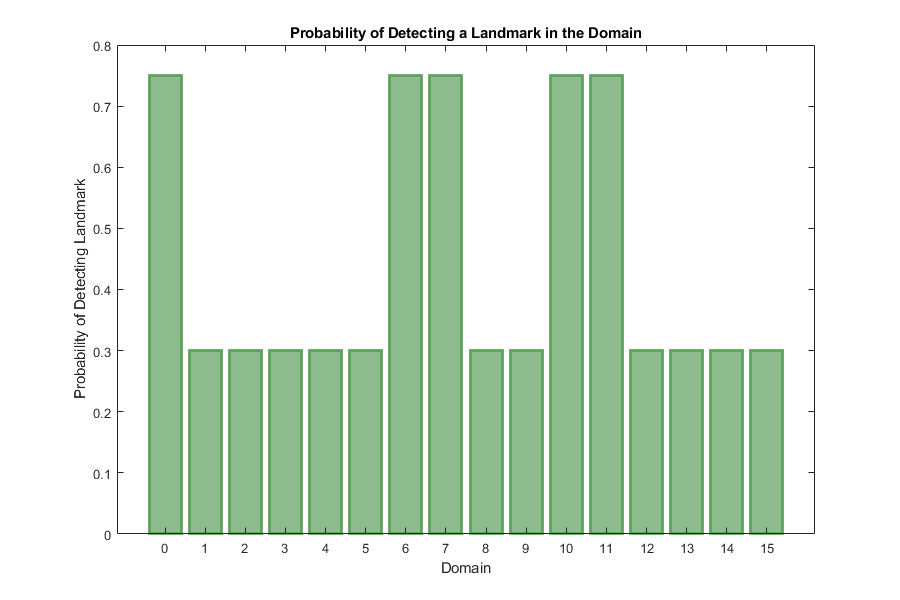

pDL = 0.75;
pDnL = 0.3;
domain = linspace(0,15,16);
pdf = zeros(1,16);
for i=1:length(domain)
    if i == 1 || i == 7 || i == 8 || i == 11 || i == 12
        pdf(i)  = pDL;
    else
        pdf(i) = pDnL;
    end
end

for i=1:length(domain)
    domain(i) = i-1;
end
figure('Position',[10 10 900 600])
bar(domain,pdf,"FaceColor",'#8fbc8f',"EdgeColor",'#5ba25b','LineWidth',2)
title('Probability of Detecting a Landmark in the Domain')
xlabel('Domain')
ylabel('Probability of Detecting Landmark')
xticks(domain)

sumPDF = sum(pdf);
fprintf("The integration of the probabilities above is: %.2f",sumPDF)

The integration of the probabilities above is: 7.05

### The integration of the proabilities in the bar graph above is 7.05 which is greater than 1, therefore it is not a proper density function

# 2) Describe in words the initial belief for the location of the robot and provide a plot of the prior belief as a bar graph.

### The initial belief is the is the probability that the robot is beginning at a location with a landmark. 

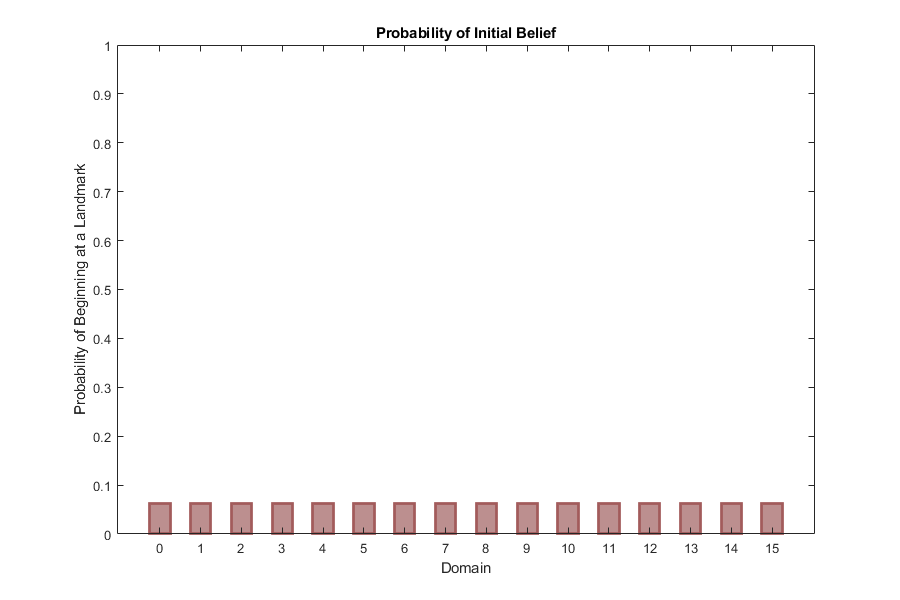

pLandmark = 5/16;
pNoLandmark = 1-pLandmark;
initialBel = zeros(1,16);
for i=1:length(initialBel)
    if i == 1
        initialBel(i)  = pLandmark/5;
    else
        initialBel(i) = pNoLandmark/11;
    end
end
figure("Position",[10 10 900 600])
bar(domain,initialBel,0.5,'FaceColor','#bc8f8f',"EdgeColor","#a25b5b","LineWidth",2)
title("Probability of Initial Belief")
ylabel('Probability of Beginning at a Landmark')
xlabel('Domain')
xticks(domain)
ylim([0 1])

# 3) Assuming for a single time step the robot makes a measurement and then carries out a control input. Define an array, z, that contains the measurements and an array, u, that contains the control inputs.

z = [1,1,1,0,-1] %1 denotes a detection, 0 denotes no detection, -1 denotes no measurement

z =      1     1     1     0    -1


u = [0,4,-5,-7,0] %0 is no movement, all others represent movement on the cirlce

u =      0     4    -5    -7     0


# 4) Describe in words what the motion model for this problem should be. Keep in mind the circular nature of the spots descirbed in the prompt. Given this motion model, provide an intuitive guess where the robot should be at the end of sequence of measurements and control inputs defined in the prompt.

### The motion model for the robot will be traveling between nodes on the circle by the input for how far the robot should move plus the previous steps position. If the value exceeds 16 a remainder function will be used to determine the node number value. If the value is negative then 16 subtracted from the opposite of the remainder will give the node number. 

### Pseudo code

### 
$$x_t = x_{t-1}+u$$


### if $x_t \geq 16$: $x_t = remainder(x_t,16)$

### else if $x_t < 0:x_t = 16-remainder(-x_t,16)$

### Given this model and the prompts input functions my guess is the robot will be at position 15 at the end of the sequence (starting at 7). If all of the input sequence and resulting measurments are to be believed this is the only location that satisfies the motion.

# 5) Implement a recursive Bayesian filter to numerically arrive at the final belief distribution for the location of the robot. The motion update is deterministic. This implimentation should take the form of a for loop with a measurement update followed by a motion update. Plot the (final) posterior belief as a bar graph. How does the result compare with your intuition from the previous problem?

### Algorithm Pseudo code

Set up:

Generate a matrix of all possible combinations to go from any domain point to a landmark location (cw or ccw) (**UNSUED**)

initialize the prior, probability of location given a movement, and initial belief

- Generate a prior $\overline {bel} = \sum P(x_t|x_{t-1},u_t)bel(x_{t-1})$  (this is initalized at the start and then calculated everytime after)

- See if there is a measurement available

- Correct prior $bel(x_t) = \eta P(z_t|x_t)\overline{bel}(x_t)$

- If the measurment is z=1 it means a landmark was detected. Two possibilites exist for each location, the measurement was correct or the measurement was incorrect. Calculate both

- If the measurement is z=0 it means a landmark was not detected. Again two possibilities for each location, the measurement was correct or incorrect. Calculate both

- based on the if statement only do this once: Calculate eta based on the two possibilities at a location, then update the belief to the correct measurment probability and divide by total number of domain points.

- set the prior beleif to the current beleif

- update motion

- If the robot didn't move then probability of location given a movement remains constant

- If the robot did move check the given input with the landmark location matrix. If a given u is a possible value for one of the locations then location probability = 1, otherwise 0

- Repeat until all motions completed

%Define all the probabilities (UNUSED)
pLD = (pDL*pLandmark)/(pDL*pLandmark+pDnL*pNoLandmark); %P(L|D)
% pLnD = ((1-pDL)*pLandmark)/((1-pDL)*pLandmark+(1-pDnL)*pNoLandmark); %P(L|!D)
% pnLnD = ((1-pDnL)*pNoLandmark)/((1-pDnL)*pNoLandmark+(1-pDL)*pLandmark); % P(!L|!D)
% pnLD = ((pDnL)*pNoLandmark)/((1-pDnL)*pNoLandmark+pDL*pLandmark); %P(!L|D) 
% 
% initialbel1 = (pLD*pLandmark+pLnD*pNoLandmark)/5;
% initialbel2 = (pnLD*pLandmark+pnLnD*pNoLandmark)/11;
% eta = 1/(initialbel2+initialbel1);
% initialbel1 = eta*initialbel1;
% initialbel2 = eta*initialbel2;

%set init to true so that the first prior belief is initialized to the
%initial belief
init = true;
% x0 = randi([0 15],1,1); %some random position in the domain
%generate a random position in the domain with slightly higher weight given
%to landmark locations
pdf = pdf./(sum(pdf));
x0 = randsample(16,1,true,pdf);
x0 = x0-1; %scale to 0 - 15

% the domain
x = zeros(1,length(u));

%Setup matrix of inputs for a given location that could have you land on a
%landmark with certainty
uLandmark(1,:) = [-10 -9 -6 -5 0 6 7 10 11 16]; %if you move any of these amounts at zero you will hit a landmark
%
for i=1:length(domain)
    if i<=6
        uLandmark(i+1,:) = uLandmark(i,:)-1;
    elseif i == 8
        uLandmark(i,:) = [-16 -13 -12 -7 -1 0 3 4 9 15];
    elseif i == 9
        uLandmark(i,:) = [-14 -13 -8 -2 -1 2 3 8 14 15];
    elseif i <= 11
        uLandmark(i,:) = uLandmark(i-1,:)-1;
    elseif i == 12
        uLandmark(i,:) = [-16 -11 -5 -4 -1 0 5 11 12 15];
    elseif i == 13
        uLandmark(i,:) = [-12 -6 -5 -2 -1 4 10 11 14 15];
    elseif i<=16
        uLandmark(i,:) = uLandmark(i-1,:)-1;
    end
end
%get the size of the input landmark matrix
[v,n] = size(uLandmark);
%probability of state given input
pXU = zeros(1,length(domain));
%initialize bel matrix (want the time history)
bel = zeros(length(u)+1,length(domain));
%set initial bel
bel(1,:) = initialBel; %initial prior
%initialize the prior belief vector
pbel = zeros(1,length(domain));
%Bayesian Filter
%loop over measurement domain
for i=1:length(z)
    %if we are intializing
    if init 
       pbel = bel(1,:); %set prior bel to the initial bel
       init = false; %turn off init
    %if the input is 0 (can't happen on first loop since init is true
    elseif u(i) == 0 
        disp('No movement') %print out no movement
        pbel = oldbel; %set pbel to oldbel (from measurement model)
    %otherwise there is a movement and we need to figure out the
    %probability of hitting or not hitting a landmark given the previous
    %location, the input and the last measurement
    else 
        fprintf('Robot moves %d',u(i)) %print out the movement specified
        %loop over domain in input landmark matrix (UNUSED in Final
        %solution submission)
        for k=1:length(domain)
            %loop over the possible inputs that would result in hitting a landmark
            for h=1:n
                %if the input would move the current domain item in ULandmark to a landmark and the measurment is says there was a landmark
                if u(i) == uLandmark(k,h) && z(i) == 1 
                    %P(L | L, U, z) or P(L | !L, U, z) = 1
                    pXU(k) = 1; %certainty of hitting a landmark is 1 if you were at a landmark or if you were not at a landmark
                    break %stop from overwritting pXU for this input
                %if the input would not move the current domain item in ULandmark to a landmark and no detection of a landmark was made
                elseif u(i) ~= uLandmark(k,h) && z(i) == 0 
                    %P(!L | L, U, z) or P(!L | !L, U, z) = 1
                    pXU(k) = 1; %certainty of not hitting a landmark is 1 if you were at a landmark or not at a landmark
                %law of total probability for previous elseif
                elseif u(i) == uLandmark(k,h) && z(i) == 0 
                    %P(L | L, U, z) or P(L | !L, U, z) = 0
                    pXU(k) = 1; %certainty of hitting a landmark for given input
                    break
                %law of total probability for first if
                else
                    %P(!L | L, U, z) or P(!L | !L, U, z) = 0
                    pXU(k) = 1; %no chance of hitting a landmark
                end     
            end
        end
        pXU; %print it for debugging
        pbel = pXU.*oldbel; %calculate prior bel
        eta = sum(pbel); %normalize
        pbel = pbel./eta; %normalize
        pbel = circshift(pbel,u(i)); %move the prior bel to corresponding location
    end
    %if a measurement is available
    if z(i) ~= -1 %I dislike this not (~) operator, bang (!) is the only not operator change my mind
        disp("measurement available")
        if z(i) == 1
           disp('Landmark Detected') 
        else
            disp('No Landmark Detected')
        end
        %loop over domain
        for j=1:length(domain)
            %if z = 1 then a landmark was detected
            if z(i) == 1
                temp1 = pDL*pbel(j); %calculate 1st bel for a location bel1 = P(D | L) * pbel (true reading)
                temp2 = pDnL*pbel(j); %calculate 2nd bel for a location bel2 = P(D | !L) * pbel (false positive)
                %if the two beliefs are zero because the location is not possible (from the prior)
                if temp1 == 0 && temp2 == 0 
                    bel(i+1,j) = 0; %bel set to zero
                %if the location is a landmark use the first belief and eta (give more weight)    
                elseif j == 1 || j == 7 || j == 8 || j == 11 || j == 12 
                    bel(i+1,j) = temp1;
                %if the location is not a landmark use the second belief
                else
                    bel(i+1,j) = temp2; 
                end
            else
                %if z = 0 no land mark was detected
                temp1 = (1-pDL)*pbel(j); %calculate 1st bel for location bel1 = P(!D | L) * pbel (false negative)
                temp2 = (1-pDnL)*pbel(j); %calculate 2nd bel for location bel2 = P(!D | !L) * pbel (true negative)
                %if the two beliefs are zero because the location is not possible (from prior)
                if temp1 == 0 && temp2 == 0 
                    bel(i+1,j) = 0; %set bel to zero
                %if the location is a landmark
                elseif j == 1 || j == 7 || j == 8 || j == 11 || j == 12 
                    bel(i+1,j) = temp1; %record as a false negative and give less weight
                else
                    bel(i+1,j) = temp2; %record as true negatives
                end
            end
        end
        eta = sum(bel(i+1,:)); %calculate eta for domain
        bel(i+1,:)=bel(i+1,:)./eta; %normalize domain probability so it sums to 1
        oldbel = bel(i+1,:); %set the oldbel to the current beleif
    else
        disp("No measurement available")
        bel(i+1,:) = bel(i,:); %next belief = last belief
        oldbel = bel(i+1,:); %set old belief
    end
    %movement update
    x(i) = x0 + u(i);
    if x(i)>=16
        x(i) = rem(x(i),16);
    elseif x(i)<0
        x(i) = 16-rem(-x(i),16);
    end
    %print out true position
    fprintf("The input u = %d moved the robot from %d to %d",u(i),x0,x(i))
    x0 = x(i);
   
end

measurement available


Landmark Detected


The input u = 0 moved the robot from 15 to 15

Robot moves 4

pbel =     0.1064    0.0426    0.0426    0.0426    0.0426    0.0426    0.1064    0.1064    0.0426    0.0426    0.1064    0.1064    0.0426    0.0426    0.0426    0.0426


pbel =     0.0426    0.0426    0.0426    0.0426    0.1064    0.0426    0.0426    0.0426    0.0426    0.0426    0.1064    0.1064    0.0426    0.0426    0.1064    0.1064


measurement available


Landmark Detected


The input u = 4 moved the robot from 15 to 3

Robot moves -5

pbel =     0.0704    0.0282    0.0282    0.0282    0.0704    0.0282    0.0704    0.0704    0.0282    0.0282    0.1761    0.1761    0.0282    0.0282    0.0704    0.0704


pbel =     0.0282    0.0704    0.0704    0.0282    0.0282    0.1761    0.1761    0.0282    0.0282    0.0704    0.0704    0.0704    0.0282    0.0282    0.0282    0.0704


measurement available


Landmark Detected


The input u = -5 moved the robot from 3 to 14

Robot moves -7

pbel =     0.0451    0.0451    0.0451    0.0181    0.0181    0.1129    0.2822    0.0451    0.0181    0.0451    0.1129    0.1129    0.0181    0.0181    0.0181    0.0451


pbel =     0.0451    0.0181    0.0451    0.1129    0.1129    0.0181    0.0181    0.0181    0.0451    0.0451    0.0451    0.0451    0.0181    0.0181    0.1129    0.2822


measurement available


No Landmark Detected


The input u = -7 moved the robot from 14 to 7

No movement


No measurement available


The input u = 0 moved the robot from 7 to 7

disp(x)

    15     3    14     7     7



disp(bel(end,:))

  Columns 1 through 12

    0.0181    0.0203    0.0507    0.1269    0.1269    0.0203    0.0072    0.0072    0.0507    0.0507    0.0181    0.0181

  Columns 13 through 16

    0.0203    0.0203    0.1269    0.3171



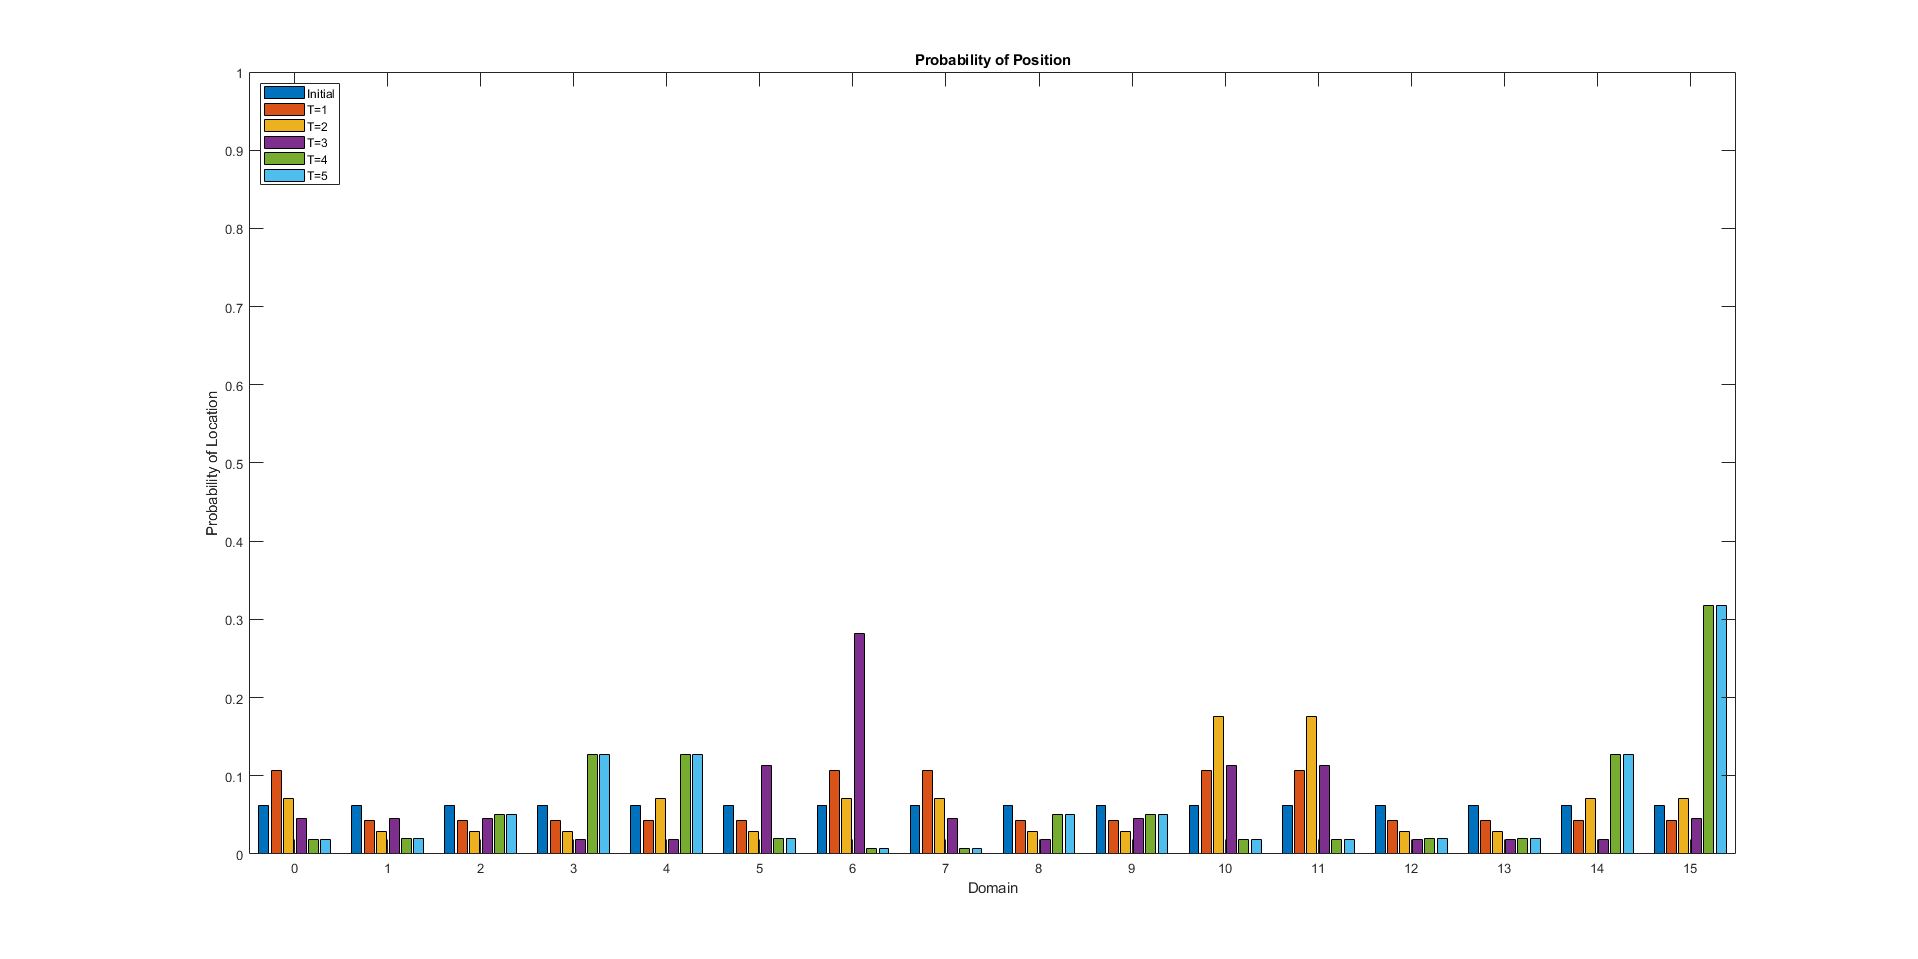

%figure for pretty plot
figure("Position",[10 10 2000 1000])
bar(domain,bel);
hold on
%bar(x(1,end),1,0.1,'red')
title("Probability of Position")
xlabel("Domain")
ylabel("Probability of Location")
xticks(domain)
ylim([0 1])
legend(["Initial","T=1","T=2","T=3","T=4","T=5"],"Location",'northwest')

### The result compares well to my intuition from problem 4. Highest probability is for now false positives. However, location 3, 4, 14 have the next highest probability becuase the 1st measurement could have been a false positive.

# PART 2

#### Now, we are going to implement a linear Kalman filter with provided simulated data. The premise is similar to that from SHW #3. Let's assume we have a cobot designed to assist with upper extremity rehabilitation following a stroke by guiding a hand's trajectory through a sequence of predefined movements. Assume the design of the cobot includes an accelerometer collocated with the handle that is capable of measuring the acceleration in the horizontal plane resolved in the world frame.

#### The states we are interested in estimating are the (x, y) position, which requires us to estimate the (x, y) velocity as well. Also assume the experimental set up inclues a sensor (e.g., UWB RF sensor) that is providing position data at a much lower frequency than the accelerometer. Unfortunately, the sensor only recorded data starting halfway through the trial.

#### The MATLAB data files provides thruth position (p) and velocity (v) as well as measured acceleration (a), UWB RF measurements (z), and the time vector (t) for the dataset (in seconds). For position, velocity, and acceleration, the first column contains the data for the x-axis and the second column contains the data for the y-axis. For the UWB RF measurements, the first column contains the indices when the measurements are made, the second column contains the data for the x-axis and the thrid column contains the data for the y-axis. Assume the acceleration is corrupted by zero mean Gaussian measurement noise ($\sigma_a = 0.15 \frac{ft}{s^2}$). While we will be ignoring it here, there is also a random walk bias corrupting the acceleration data as well. Also assume the UWB RF measurmeents are corrupted by zero mean Gaussian measurement noise ($\sigma_z = 0.1 ft$). Feel free to use the first index of the truth position and velocity data for initial conditions.

# 6) Provide the motion model describing how the states described in the prompt that we want to estimate for this system are propagated (ch6). Also provide an equation describing how the error covariance matrix is propagated as well (with an appropriate definition for the process noise). Implement a recursive **for** loop that uses these models to estimate the states and error covariance matrix at every instance in time during the data collection - pay special attention to the deminesions of the matrices and vectors. Provide the following:

- A plot of the estimated and true trajectories (plot the x-y pos.). Include labels and units. Comment on how the trajectories compare.

- A plot of the estimated and true positions as functions of time and a plot of the estimated and true velocities as functions of time. Include labels and units. Comment on how the estimates compare with the true values.

- A plot of the determinant of the error covariance matrix as a function of time. Include labels and units. Comment on the magnitude of the error covariance. 

### Motion Model

## 
$$\hat x_k = \pmatrix{\hat p_{x,k}\cr\hat p_{y,k}\cr \hat v_{x,k}\cr \hat v_{y,k}}=\pmatrix{1 & 0 & \Delta t & 0\cr 0 & 1 & 0 & \Delta t\cr 0 & 0 & 1 & 0\cr 0 & 0 & 0 & 1}\pmatrix{\hat p_{x,k-1}\cr\hat p_{y,k-1}\cr \hat v_{x,k-1}\cr \hat v_{y,k-1}}+\pmatrix{0\cr 0\cr \Delta t\cr \Delta t}\pmatrix{a_{x,k} & a_{y,k}}$$


### Error Covariance (Px)

## $\hat P_k = A\hat P_{k-1}A^T + Q$, $A =\pmatrix{1 & 0 & \Delta t & 0\cr 0 & 1 & 0 & \Delta t\cr 0 & 0 & 1 & 0\cr 0 & 0 & 0 & 1}$, $Q = \pmatrix{\sigma_{a,x} & 0 & 0 & 0\cr 0 & \sigma_{a,y} & 0 & 0\cr 0 & 0 & \sigma_{a,x}\Delta t & 0\cr 0 & 0 & 0 & \sigma_{a,x}\Delta t }$

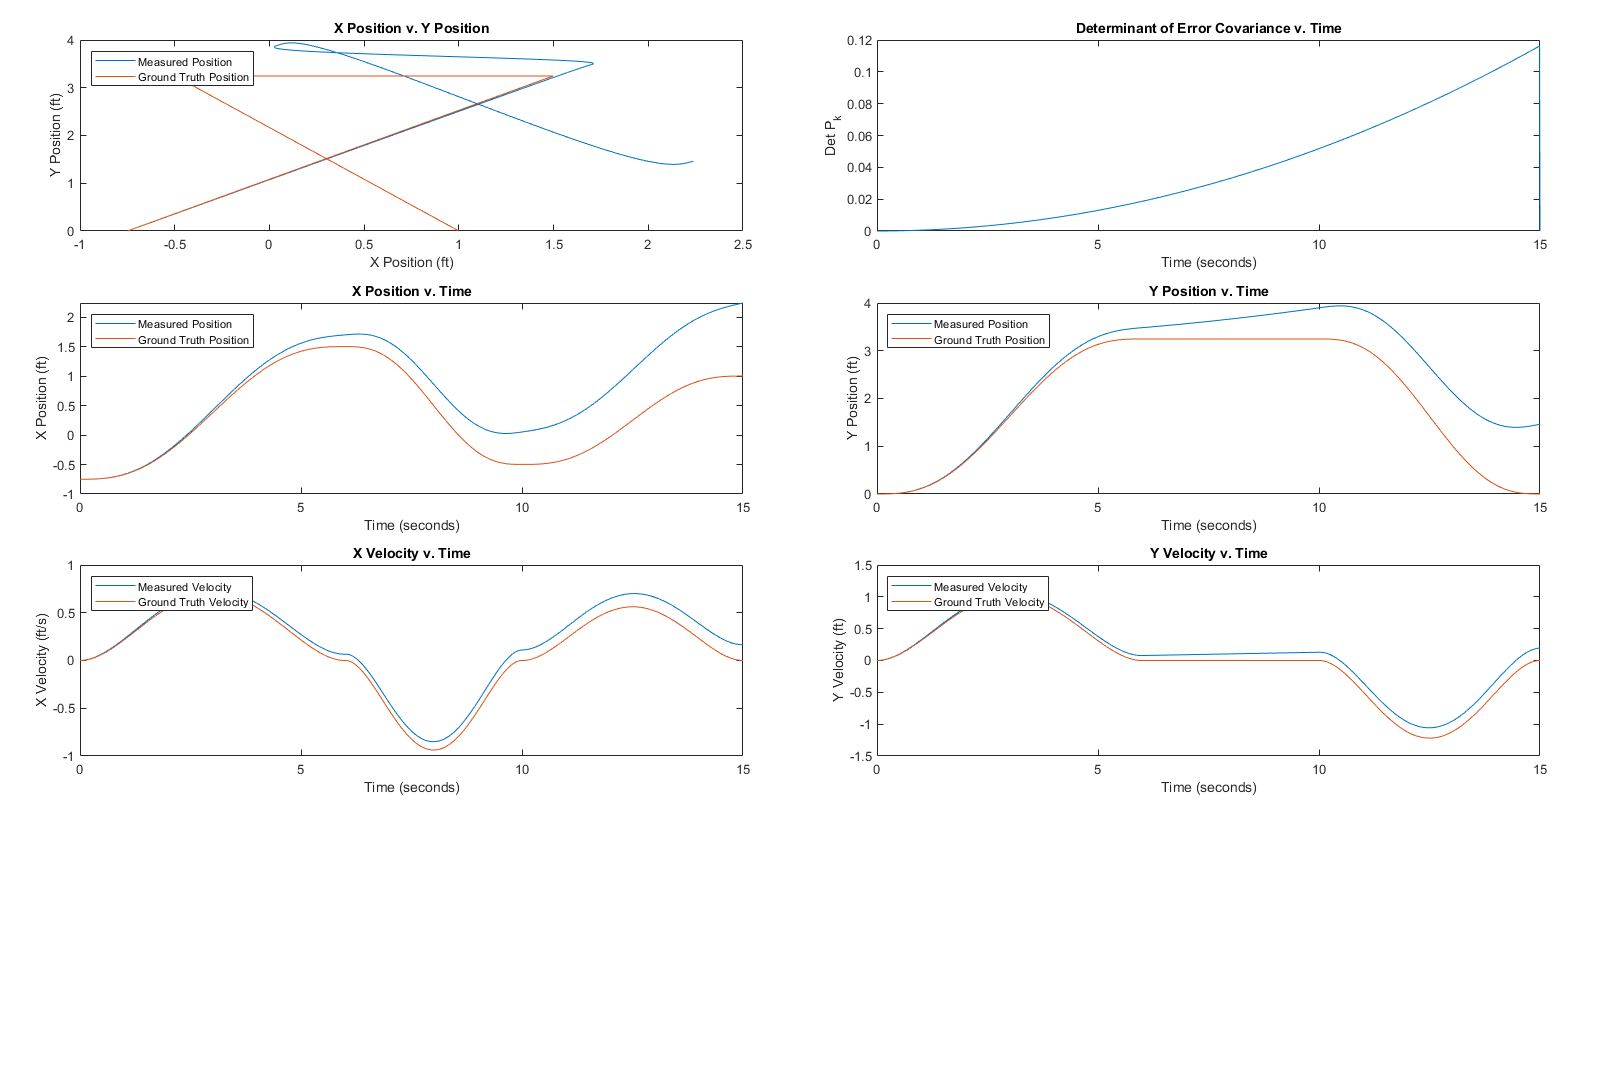

load("data (2).mat")

%let's put everything into a structure to make our life easier
data.a.x = a(1,:);
data.a.y = a(2,:);
data.v.x = v(:,1);
data.v.y = v(:,2);
data.p.x = p(:,1);
data.p.y = p(:,2);
data.time = t;
data.z.x = z(:,2);
data.z.y = z(:,3);
data.z.time = z(:,1);
clear a z p t v %get rid of duplicate variables

%initial conditions
initial_x = data.p.x(1,1);
initial_y = data.p.y(1,1);
initial_Vx = data.v.x(1,1);
initial_Vy = data.v.y(1,1);

%integrate the data (USE THE LINEAR MODEL YOU WROTE!)
% measuredVelocityX = cumtrapz(data.time,data.a.x)+initial_Vx;
% measuredVelocityY =  cumtrapz(data.time,data.a.y)+initial_Vy;
% measuredPositionX = cumtrapz(data.time,measuredVelocityX)+initial_x;
% measuredPositionY = cumtrapz(data.time,measuredVelocityY)+initial_y;

x_k = zeros(length(data.time),4);
x_k(1,:) = [initial_x, initial_y,initial_Vx,initial_Vx];
p_k_prev = zeros(4,4);
Q = eye(4);
sigma_a = 0.15;
Q = sigma_a*Q;
detPk = zeros(1,length(data.time));
A = eye(4);
a_k = [zeros(1,length(data.time));zeros(1,length(data.time));data.a.x;data.a.y]';
for i=1:length(data.time)
    if i<length(data.time)
        deltaT = data.time(i+1)-data.time(i);
        DeltaT = [0; 0; deltaT; deltaT];
        DeltaT.*a_k(i,:)';
        A(1,3) = deltaT;
        A(2,4) = deltaT;
        x_k(i+1,:) = A*x_k(i,:)'+DeltaT.*a_k(i,:)';
        Q(3,3) = Q(3,3)*deltaT;
        Q(4,4) = Q(4,4)*deltaT;
        p_k_ = A*p_k_prev*inv(A)+Q;
        p_k_prev = p_k_;
        detPk(i) = det(p_k_);
    end
end
measuredPositionX = x_k(:,1);
measuredPositionY = x_k(:,2);
measuredVelocityX = x_k(:,3);
measuredVelocityY = x_k(:,4);

figure("Position",[10,10, 2100,1400])
t=tiledlayout(4,2);
t.Padding = "compact";
t.TileSpacing = 'loose';
%Plot of X v. Y position
ax1 =  nexttile;
plot(ax1,measuredPositionX,measuredPositionY);
hold on
plot(data.p.x,data.p.y);
hold off
title(ax1,"X Position v. Y Position")
ylabel(ax1,"Y Position (ft)")
xlabel(ax1,'X Position (ft)');
legend(["Measured Position","Ground Truth Position"],"Location",'northwest')
ax2=nexttile;
plot(ax2,data.time,detPk);
title(ax2,"Determinant of Error Covariance v. Time")
ylabel(ax2,"Det P_k")
xlabel(ax2,'Time (seconds)');
%Plot of X v. Time
ax3 =  nexttile;
plot(ax3,data.time,measuredPositionX);
hold on
plot(data.time,data.p.x);
hold off
title(ax3,"X Position v. Time")
ylabel(ax3,"X Position (ft)")
xlabel(ax3,'Time (seconds)');
legend(["Measured Position","Ground Truth Position"],"Location",'northwest')
ax4=nexttile;
plot(ax4,data.time,measuredPositionY);
hold on
plot(ax4,data.time,data.p.y);
hold off
title(ax4,"Y Position v. Time")
ylabel(ax4,"Y Position (ft)")
xlabel(ax4,'Time (seconds)');
legend(["Measured Position","Ground Truth Position"],"Location",'northwest')
%Plot of X v. Time
ax5 =  nexttile;
plot(ax5,data.time,measuredVelocityX);
hold on
plot(data.time,data.v.x);
hold off
title(ax5,"X Velocity v. Time")
ylabel(ax5,"X Velocity (ft/s)")
xlabel(ax5,'Time (seconds)');
legend(["Measured Velocity","Ground Truth Velocity"],"Location",'northwest')
ax6=nexttile;
plot(ax6,data.time,measuredVelocityY);
hold on
plot(ax6,data.time,data.v.y);
hold off
title(ax6,"Y Velocity v. Time")
ylabel(ax6,"Y Velocity (ft)")
xlabel(ax6,'Time (seconds)');
legend(["Measured Velocity","Ground Truth Velocity"],"Location",'northwest')

## Comments:

### The trajecoties in the first graph match up until the y value goes constant, here our model predicts both x and y continue to grow, this then leads to the horizontal traverse not being as large as it should as well as y continuing to increase instead of remaining constant. Then at the next turn the model fails to make a sharp turn and does a large loop. This ultimately results in the final position being significantly different from the actual position.

### Again the position graphs show a much higher deviation from the true values after 5 seconds when that sharp left turn is made. The velocities in comparison have a much smaller magnitude in deviation but show the same overal trend in increasing deviation after 5 seconds.

### Error covariance determinante appears to increase exponentially as time progresses. This clearly shows why the deviation in the position and velocities grows increasingly as time progresses. 

# 7) Now, include an update step into the implementation from the previous question to include the additional measurements provided by the UWB RF sensor. Bear in mind the first column in var z denotes the indicies of the time from the time vector when measurements are made, not the times themselves. Provide the following:

- A plot of the estimated and true trajectories (i.e., plot the x-y position).Include labels and units. Comment on how the trajectories comparewith the true values and the uncorrected estimatesfrom the previous question.

- Aplot of the estimated and true positions as functions of time and a plot of the estimated and true velocities as functions of time.Include labels and units.Comment on how the corrected estimates compare with the true values and the uncorrected estimates from the previous question.

- A plot of the determinant of the error covariance matrix as a function of time.Include labels and units.Comment on the magnitude of the error covarianceand how it compares to the plot from the previous question.

##  
$$\mathcal{I}_k= y_k - \hat y_k = p_{m,k}-\hat p_k$$


##  $S_k = H_K\hat P^-_kH^T_k+R$, $H_k = \pmatrix{1&0&0&0\cr0&1&0&0}$, $R = \pmatrix{\sigma_z^2 & 0\cr 0 & \sigma_z^2 }$

## 
$$K_k = \hat P^-_kH^T_kS^{-1}_k$$


## $\Delta\hat x_k = K_k\mathcal{I}_k$, $\hat x^+_k=\hat x^-_k+\Delta\hat x_k$

## 
$$\hat P^+_k = (I-K_kH_k)\hat P^-_k$$


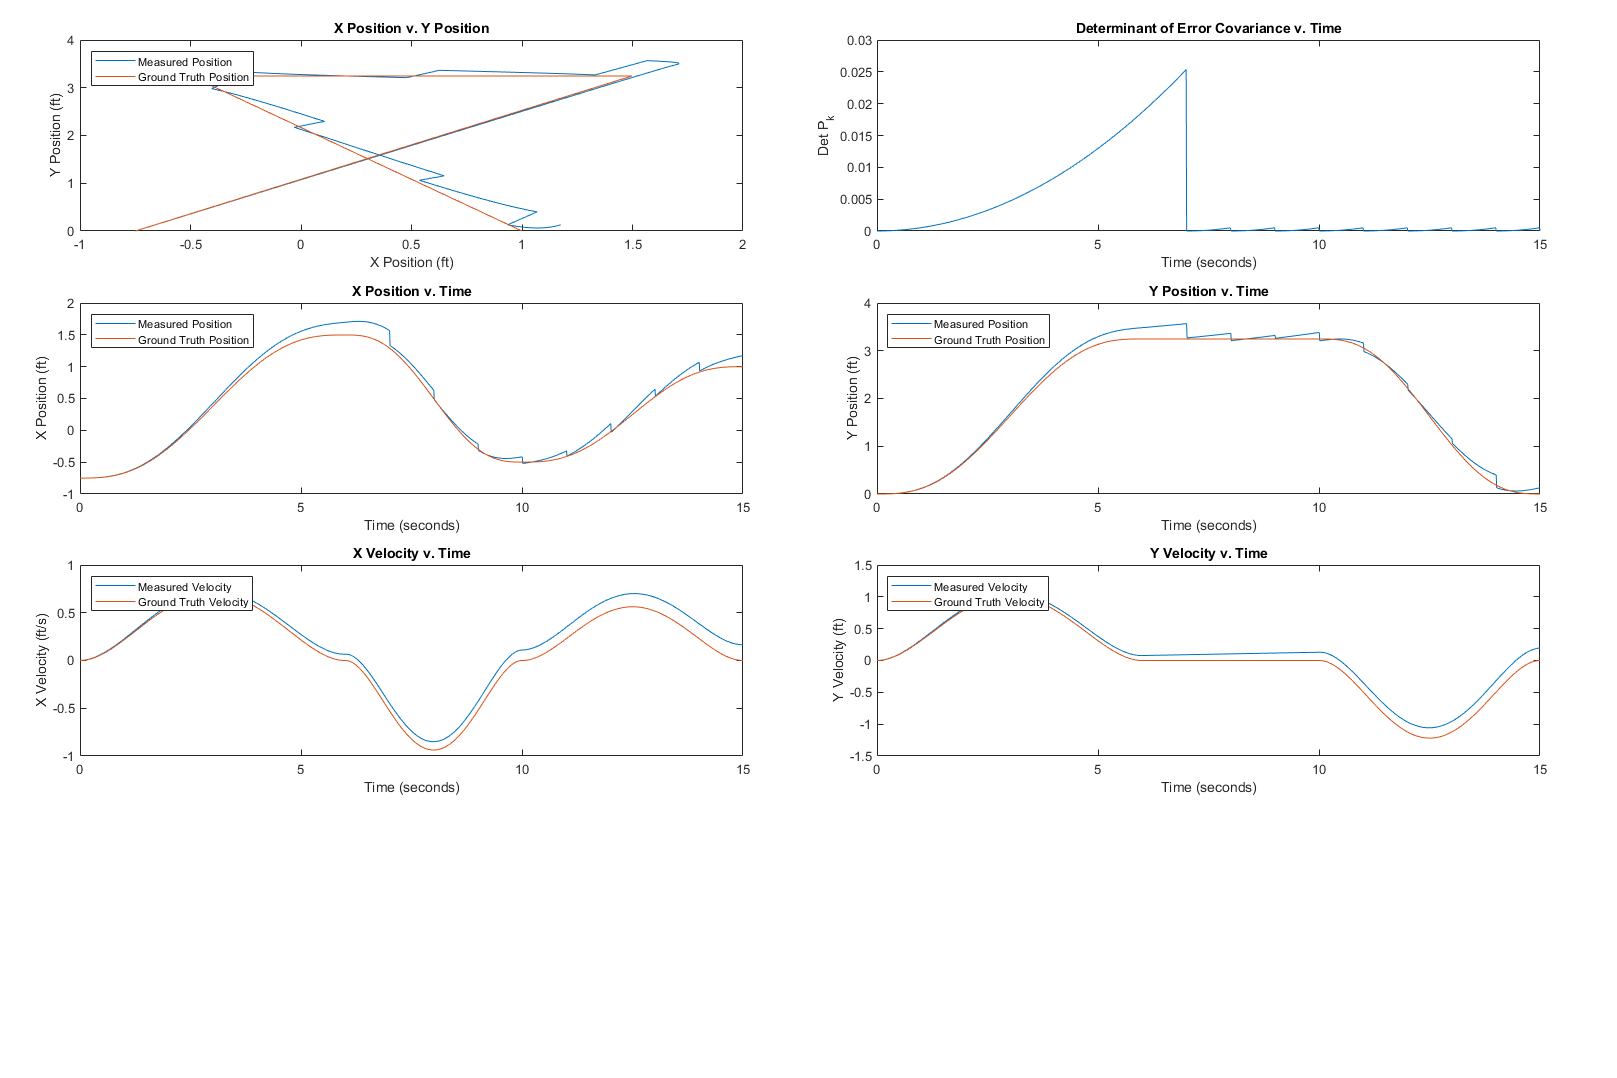

x_k = zeros(length(data.time),4);
x_k(1,:) = [initial_x, initial_y,initial_Vx,initial_Vx];
delta_x = zeros(2,1);
p_k_prev = zeros(4,4);
Q = eye(4);
sigma_a = 0.15;
Q = sigma_a*Q;
H = [1 0 0 0;0 1 0 0];
sigma_z = 0.1;
R = [sigma_z^2 0;0 sigma_z^2];
Inn = zeros(2,1);
s_k = zeros(2,2);
Kal_k = zeros(4,2);
detPk = zeros(1,length(data.time));
A = eye(4);
a_k = [zeros(1,length(data.time));zeros(1,length(data.time));data.a.x;data.a.y]';
for i=1:length(data.time)
    if i<length(data.time)
        deltaT = data.time(i+1)-data.time(i);
        DeltaT = [0; 0; deltaT; deltaT];
        DeltaT.*a_k(i,:)';
        A(1,3) = deltaT;
        A(2,4) = deltaT;
        x_k(i+1,:) = A*x_k(i,:)'+DeltaT.*a_k(i,:)';
        Q(3,3) = Q(3,3)*deltaT;
        Q(4,4) = Q(4,4)*deltaT;
        p_k_ = A*p_k_prev*inv(A)+Q;
        p_k_prev = p_k_;
        for k=1:length(data.z.time)
            if i == data.z.time(k)
                %data.z.x(k)
                %data.z.y(k)
                %x_k(i+1,1)
                %x_k(i+1,2)
                Inn(1,1) = data.z.x(k) - x_k(i+1,1);
                Inn(2,1) = data.z.y(k) - x_k(i+1,2);
                s_k = H*p_k_*H'+R;
                Kal_k = p_k_*H'*inv(s_k);
                delta_x = Kal_k*Inn;
                x_k(i+1,:) = x_k(i+1,:)+delta_x';
                %x_k(i+1,:)
                p_k_ = (eye(4)-Kal_k*H)*p_k_;
                p_k_prev = p_k_;
            end
        end
        detPk(i) = det(p_k_);
    end
end
measuredPositionX = x_k(:,1);
measuredPositionY = x_k(:,2);
measuredVelocityX = x_k(:,3);
measuredVelocityY = x_k(:,4);

figure("Position",[10,10, 2100,1400])
t=tiledlayout(4,2);
t.Padding = "compact";
t.TileSpacing = 'loose';
%Plot of X v. Y position
ax1 =  nexttile;
plot(ax1,measuredPositionX,measuredPositionY);
hold on
plot(data.p.x,data.p.y);
hold off
title(ax1,"X Position v. Y Position")
ylabel(ax1,"Y Position (ft)")
xlabel(ax1,'X Position (ft)');
legend(["Measured Position","Ground Truth Position"],"Location",'northwest')
ax2=nexttile;
plot(ax2,data.time,detPk);
title(ax2,"Determinant of Error Covariance v. Time")
ylabel(ax2,"Det P_k")
xlabel(ax2,'Time (seconds)');
%Plot of X v. Time
ax3 =  nexttile;
plot(ax3,data.time,measuredPositionX);
hold on
plot(data.time,data.p.x);
hold off
title(ax3,"X Position v. Time")
ylabel(ax3,"X Position (ft)")
xlabel(ax3,'Time (seconds)');
legend(["Measured Position","Ground Truth Position"],"Location",'northwest')
ax4=nexttile;
plot(ax4,data.time,measuredPositionY);
hold on
plot(ax4,data.time,data.p.y);
hold off
title(ax4,"Y Position v. Time")
ylabel(ax4,"Y Position (ft)")
xlabel(ax4,'Time (seconds)');
legend(["Measured Position","Ground Truth Position"],"Location",'northwest')
%Plot of X v. Time
ax5 =  nexttile;
plot(ax5,data.time,measuredVelocityX);
hold on
plot(data.time,data.v.x);
hold off
title(ax5,"X Velocity v. Time")
ylabel(ax5,"X Velocity (ft/s)")
xlabel(ax5,'Time (seconds)');
legend(["Measured Velocity","Ground Truth Velocity"],"Location",'northwest')
ax6=nexttile;
plot(ax6,data.time,measuredVelocityY);
hold on
plot(ax6,data.time,data.v.y);
hold off
title(ax6,"Y Velocity v. Time")
ylabel(ax6,"Y Velocity (ft)")
xlabel(ax6,'Time (seconds)');
legend(["Measured Velocity","Ground Truth Velocity"],"Location",'northwest')

## Comments

### The trajectory with the correlated measurements does a much better job at capturing the ture trajectory. We can see that right at the time when we get our first measurement the deviation from the true trajectory immediately decreases to nearly the true value. This is a much better result than when no measurements were available. However, since measurements aren't always available the error covariance begins to grow again, increasing the deviation from the true value until the next measurement occurs. Overall this results in a much closer estimate of the final position compared to when no measurements were available.

### In the positions v. time graphs we see that the measurement update is bringing the deviation from the true value back down to nearly identical. This however, is not affecting our velocity predictions that only come from our measurement of acceleration and as such do not see the same change. Again the deviation starts to increase from each new measurement until another is made to pull the value back down to the true one.

### The error covariance displays the same behavior as before, however, as soon as the first measurement is made the error covariance is updated by the measurement model, specifically it is modified by the Kalman gain. In this case it drops our determinant of the error covariance to nearly zero. Again we see the same step divergence here until a new measurement is made. 

# 8) Run the code from the previous question for the following scenarios:

- Multiply the process noise covariance matrix by 10^6

- Multiply the measurement noise covariance matrix by 10^6

# How did the estimates change? Specifically, how do they compare with the uncorrected estimates from question 6 and corrected estimates from question 7? How did the magnitude of the error covariance matrix change?

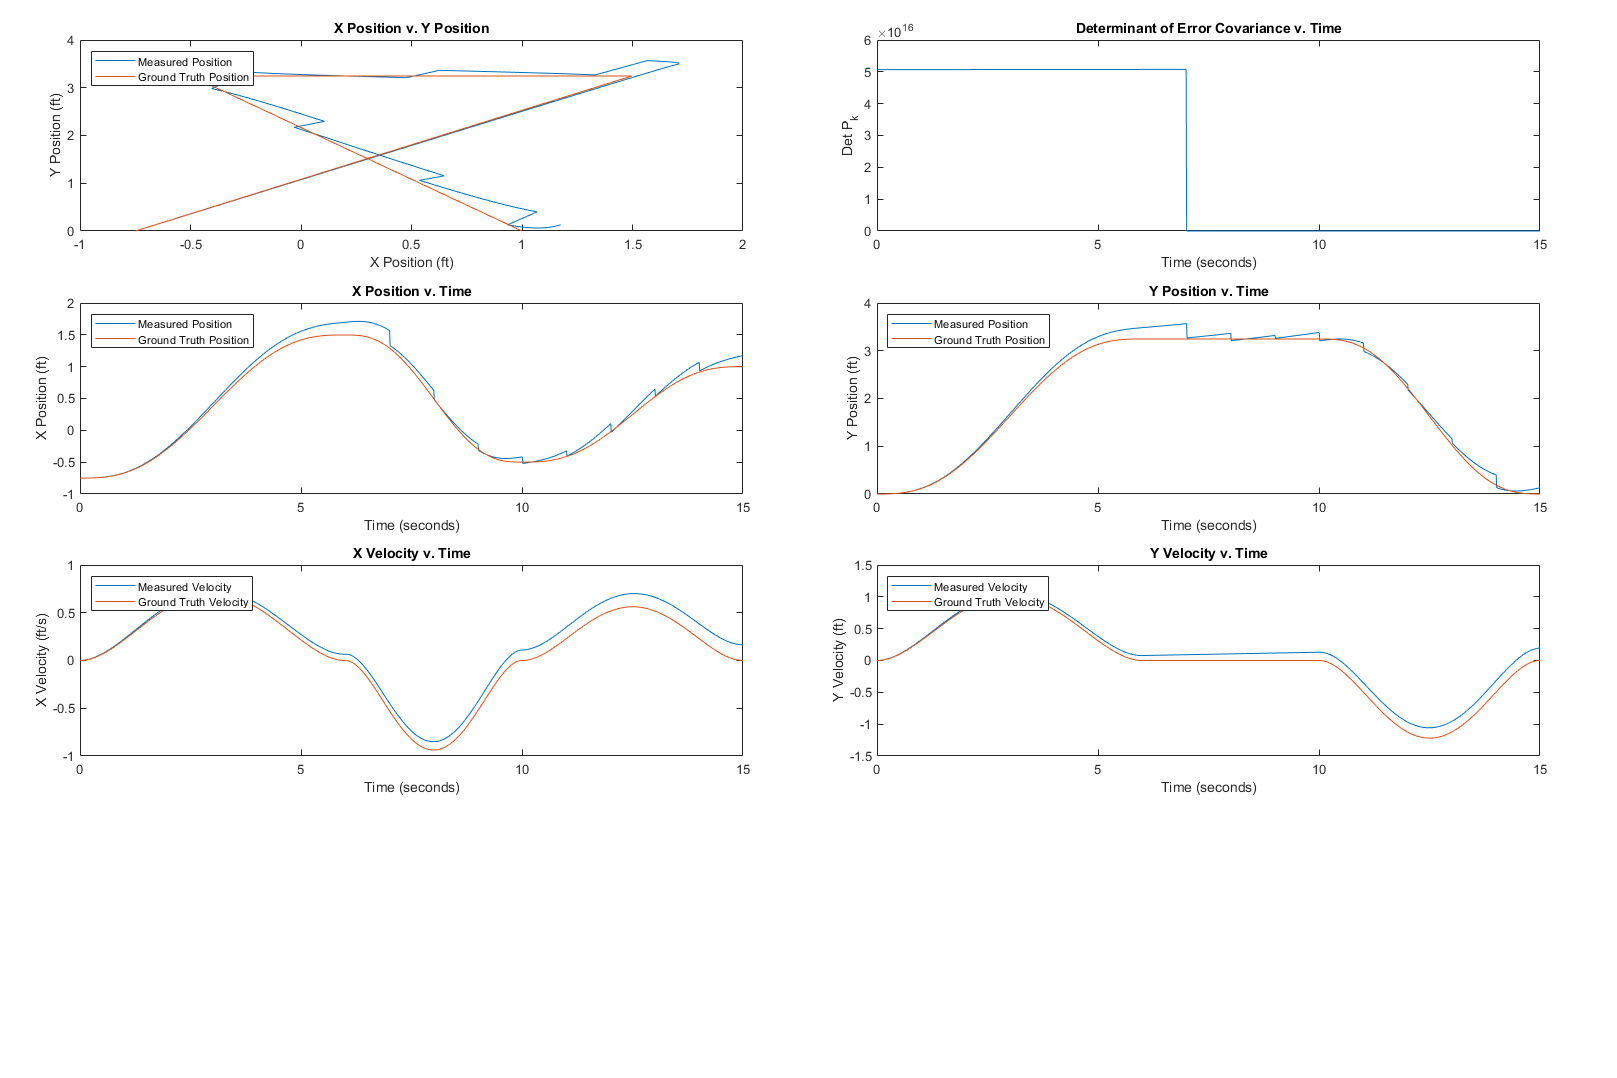

%process noise cov *10^6
x_k = zeros(length(data.time),4);
x_k(1,:) = [initial_x, initial_y,initial_Vx,initial_Vx];
delta_x = zeros(2,1);
p_k_prev = zeros(4,4);
Q = eye(4);
sigma_a = 0.15;
Q = sigma_a*Q;
H = [1 0 0 0;0 1 0 0];
sigma_z = 0.1;
R = [sigma_z^2 0;0 sigma_z^2];
Inn = zeros(2,1);
s_k = zeros(2,2);
Kal_k = zeros(4,2);
detPk = zeros(1,length(data.time));
A = eye(4);
a_k = [zeros(1,length(data.time));zeros(1,length(data.time));data.a.x;data.a.y]';
for i=1:length(data.time)
    if i<length(data.time)
        deltaT = data.time(i+1)-data.time(i);
        DeltaT = [0; 0; deltaT; deltaT];
        DeltaT.*a_k(i,:)';
        A(1,3) = deltaT;
        A(2,4) = deltaT;
        x_k(i+1,:) = A*x_k(i,:)'+DeltaT.*a_k(i,:)';
        Q(3,3) = Q(3,3)*deltaT;
        Q(4,4) = Q(4,4)*deltaT;
        p_k_ = A*p_k_prev*inv(A)+Q;
        if i == 1
            p_k_ = p_k_*10^6;
        end
        p_k_prev = p_k_;
        for k=1:length(data.z.time)
            if i == data.z.time(k)
                %data.z.x(k)
                %data.z.y(k)
                %x_k(i+1,1)
                %x_k(i+1,2)
                Inn(1,1) = data.z.x(k) - x_k(i+1,1);
                Inn(2,1) = data.z.y(k) - x_k(i+1,2);
                s_k = H*p_k_*H'+R;
                Kal_k = p_k_*H'*inv(s_k);
                delta_x = Kal_k*Inn;
                x_k(i+1,:) = x_k(i+1,:)+delta_x';
                %x_k(i+1,:)
                p_k_ = (eye(4)-Kal_k*H)*p_k_;
                p_k_prev = p_k_;
            end
        end
        detPk(i) = det(p_k_);
    end
end
measuredPositionX = x_k(:,1);
measuredPositionY = x_k(:,2);
measuredVelocityX = x_k(:,3);
measuredVelocityY = x_k(:,4);

figure("Position",[10,10, 2100,1400])
t=tiledlayout(4,2);
t.Padding = "compact";
t.TileSpacing = 'loose';
%Plot of X v. Y position
ax1 =  nexttile;
plot(ax1,measuredPositionX,measuredPositionY);
hold on
plot(data.p.x,data.p.y);
hold off
title(ax1,"X Position v. Y Position")
ylabel(ax1,"Y Position (ft)")
xlabel(ax1,'X Position (ft)');
legend(["Measured Position","Ground Truth Position"],"Location",'northwest')
ax2=nexttile;
plot(ax2,data.time,detPk);
title(ax2,"Determinant of Error Covariance v. Time")
ylabel(ax2,"Det P_k")
xlabel(ax2,'Time (seconds)');
%Plot of X v. Time
ax3 =  nexttile;
plot(ax3,data.time,measuredPositionX);
hold on
plot(data.time,data.p.x);
hold off
title(ax3,"X Position v. Time")
ylabel(ax3,"X Position (ft)")
xlabel(ax3,'Time (seconds)');
legend(["Measured Position","Ground Truth Position"],"Location",'northwest')
ax4=nexttile;
plot(ax4,data.time,measuredPositionY);
hold on
plot(ax4,data.time,data.p.y);
hold off
title(ax4,"Y Position v. Time")
ylabel(ax4,"Y Position (ft)")
xlabel(ax4,'Time (seconds)');
legend(["Measured Position","Ground Truth Position"],"Location",'northwest')
%Plot of X v. Time
ax5 =  nexttile;
plot(ax5,data.time,measuredVelocityX);
hold on
plot(data.time,data.v.x);
hold off
title(ax5,"X Velocity v. Time")
ylabel(ax5,"X Velocity (ft/s)")
xlabel(ax5,'Time (seconds)');
legend(["Measured Velocity","Ground Truth Velocity"],"Location",'northwest')
ax6=nexttile;
plot(ax6,data.time,measuredVelocityY);
hold on
plot(ax6,data.time,data.v.y);
hold off
title(ax6,"Y Velocity v. Time")
ylabel(ax6,"Y Velocity (ft)")
xlabel(ax6,'Time (seconds)');
legend(["Measured Velocity","Ground Truth Velocity"],"Location",'northwest')

## Comments about multiplying process error cov by 10^6

### The biggest differences between this result, multiplying the error covariance by 10^6, and the orginal are in the trajecotry and error covariance determinant plot. In the trajectory the deviations in Y are noticable larger when moving in both X and Y as well as the initial deviation at the left hand turn being much sharper. In the error covariance acts as a step change when the filter enters into the measurement update and scales the value down from ~10^6 to nearly zero.

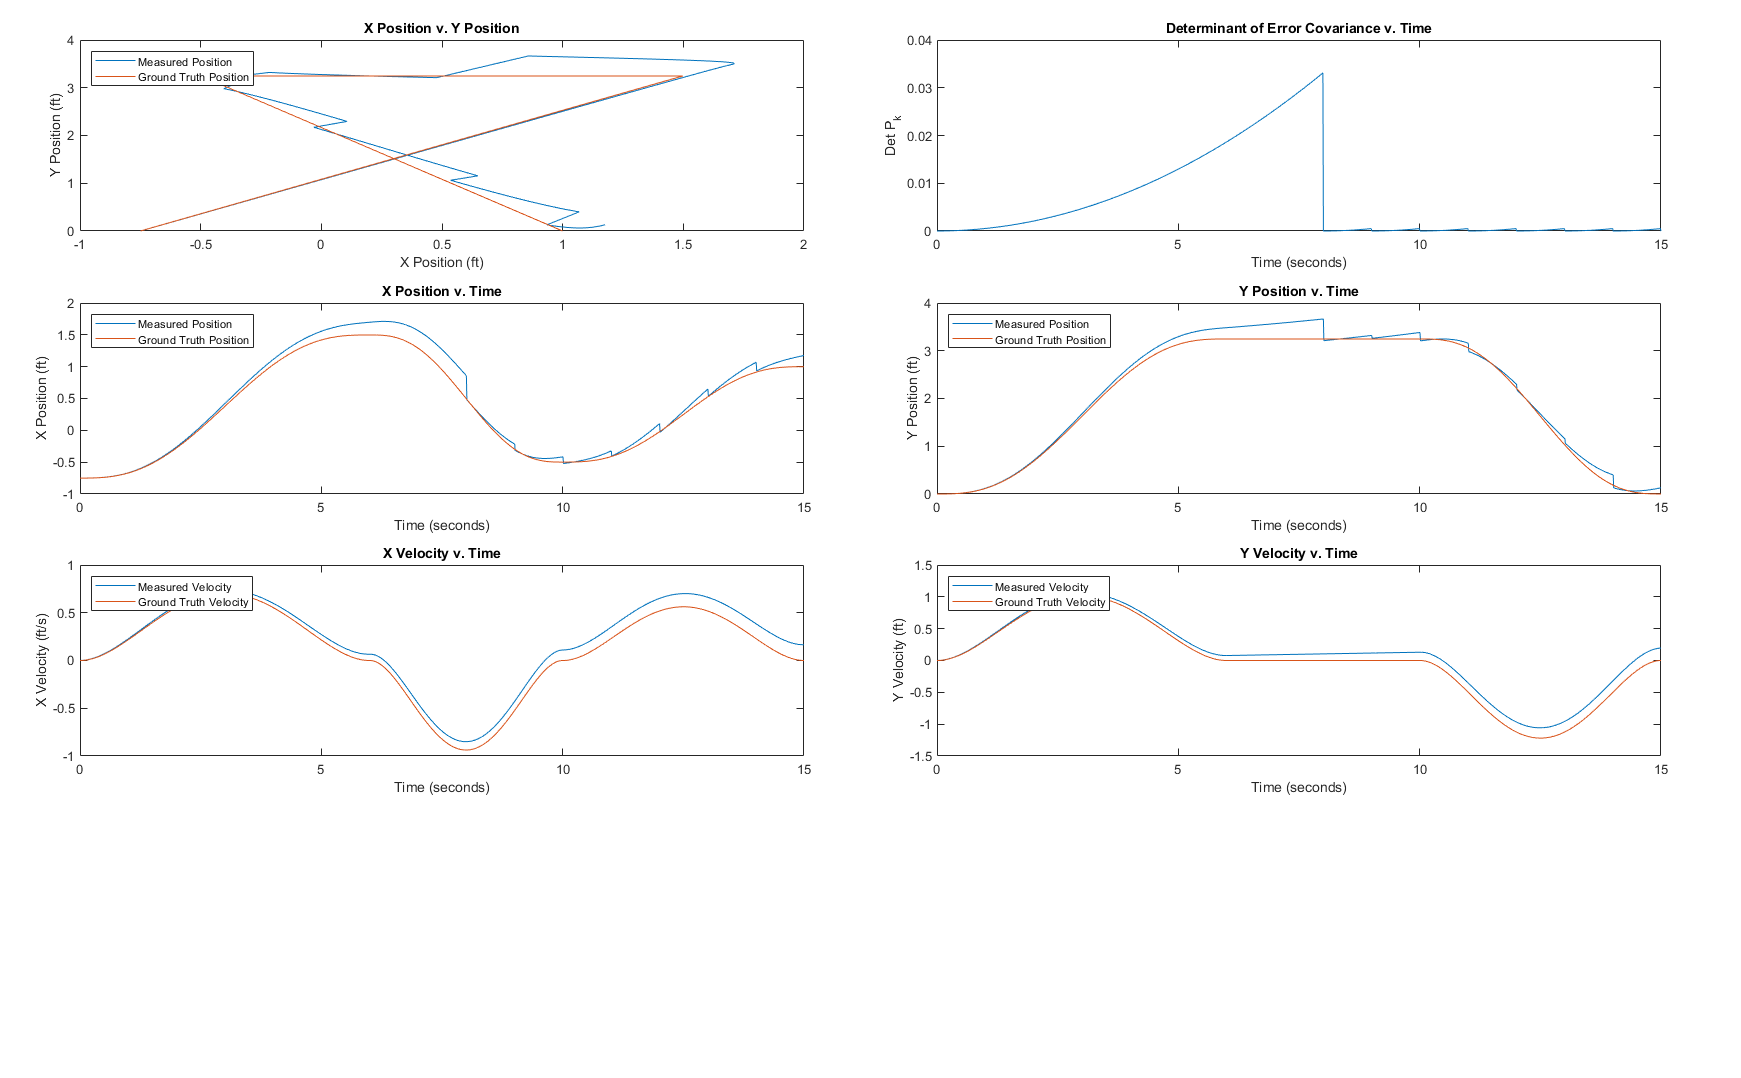

%measurement noise cov *10^6
x_k = zeros(length(data.time),4);
x_k(1,:) = [initial_x, initial_y,initial_Vx,initial_Vx];
delta_x = zeros(2,1);
p_k_prev = zeros(4,4);
Q = eye(4);
sigma_a = 0.15;
Q = sigma_a*Q;
H = [1 0 0 0;0 1 0 0];
sigma_z = 0.1;
R = [sigma_z^2 0;0 sigma_z^2];
Inn = zeros(2,1);
s_k = zeros(2,2);
Kal_k = zeros(4,2);
detPk = zeros(1,length(data.time));
A = eye(4);
a_k = [zeros(1,length(data.time));zeros(1,length(data.time));data.a.x;data.a.y]';
init = true;
for i=1:length(data.time)
    if i<length(data.time)
        deltaT = data.time(i+1)-data.time(i);
        DeltaT = [0; 0; deltaT; deltaT];
        DeltaT.*a_k(i,:)';
        A(1,3) = deltaT;
        A(2,4) = deltaT;
        x_k(i+1,:) = A*x_k(i,:)'+DeltaT.*a_k(i,:)';
        Q(3,3) = Q(3,3)*deltaT;
        Q(4,4) = Q(4,4)*deltaT;
        p_k_ = A*p_k_prev*inv(A)+Q;
        p_k_prev = p_k_;
        for k=1:length(data.z.time)
            if i == data.z.time(k)
                %data.z.x(k)
                %data.z.y(k)
                %x_k(i+1,1)
                %x_k(i+1,2)
                Inn(1,1) = data.z.x(k) - x_k(i+1,1);
                Inn(2,1) = data.z.y(k) - x_k(i+1,2);
                s_k = H*p_k_*H'+R;
                if init
                    init = false;
                    s_k = s_k*10^6;
                end
                Kal_k = p_k_*H'*inv(s_k);
                delta_x = Kal_k*Inn;
                x_k(i+1,:) = x_k(i+1,:)+delta_x';
                %x_k(i+1,:)
                p_k_ = (eye(4)-Kal_k*H)*p_k_;
                p_k_prev = p_k_;
            end
        end
        detPk(i) = det(p_k_);
    end
end
measuredPositionX = x_k(:,1);
measuredPositionY = x_k(:,2);
measuredVelocityX = x_k(:,3);
measuredVelocityY = x_k(:,4);

figure("Position",[10,10, 2100,1300])
t=tiledlayout(4,2);
t.Padding = "compact";
t.TileSpacing = 'loose';
%Plot of X v. Y position
ax1 =  nexttile;
plot(ax1,measuredPositionX,measuredPositionY);
hold on
plot(data.p.x,data.p.y);
hold off
title(ax1,"X Position v. Y Position")
ylabel(ax1,"Y Position (ft)")
xlabel(ax1,'X Position (ft)');
legend(["Measured Position","Ground Truth Position"],"Location",'northwest')
ax2=nexttile;
plot(ax2,data.time,detPk);
title(ax2,"Determinant of Error Covariance v. Time")
ylabel(ax2,"Det P_k")
xlabel(ax2,'Time (seconds)');
%Plot of X v. Time
ax3 =  nexttile;
plot(ax3,data.time,measuredPositionX);
hold on
plot(data.time,data.p.x);
hold off
title(ax3,"X Position v. Time")
ylabel(ax3,"X Position (ft)")
xlabel(ax3,'Time (seconds)');
legend(["Measured Position","Ground Truth Position"],"Location",'northwest')
ax4=nexttile;
plot(ax4,data.time,measuredPositionY);
hold on
plot(ax4,data.time,data.p.y);
hold off
title(ax4,"Y Position v. Time")
ylabel(ax4,"Y Position (ft)")
xlabel(ax4,'Time (seconds)');
legend(["Measured Position","Ground Truth Position"],"Location",'northwest')
%Plot of X v. Time
ax5 =  nexttile;
plot(ax5,data.time,measuredVelocityX);
hold on
plot(data.time,data.v.x);
hold off
title(ax5,"X Velocity v. Time")
ylabel(ax5,"X Velocity (ft/s)")
xlabel(ax5,'Time (seconds)');
legend(["Measured Velocity","Ground Truth Velocity"],"Location",'northwest')
ax6=nexttile;
plot(ax6,data.time,measuredVelocityY);
hold on
plot(ax6,data.time,data.v.y);
hold off
title(ax6,"Y Velocity v. Time")
ylabel(ax6,"Y Velocity (ft)")
xlabel(ax6,'Time (seconds)');
legend(["Measured Velocity","Ground Truth Velocity"],"Location",'northwest')

## comments on meaurement noise cov multiplied by 10^6

### Similar results to multiplying the previous case where we multiplied the process covariance by 10^6. The real difference can be seen in all of the graphs above except for the velocities. Here we see that this multiplicative factor has a strong influence on the first measurement making it deviate significantly from the true value, however, the next measurement is able to correct for this and pull the expected value down to near the true value. 

### Overall between the two cases, the process error covariance is sensitive to a multiplication factor if no initial measurement is available for a long period of time. The measurment error covariance is sensitive to a multiplication factor until a second measurement is made. This is important to know when desinging and selecting sensors. 